# Create 3-D Plot Animations

`comet3` displays a comet plot of the data specified in $z$ versus $x$ and $y$. A comet is an animation of a marker (head) and a line (tail) tracing a growing line over the data points. The tail is a solid line that traces the entire function.

## Build a 3-D Data Set

Use the peak function to load $x$, $y$ and $z$ data as arrays. Convert the data into vectors. 

[xmat,ymat,zmat] = peaks(50); 
xvec = xmat(:);
yvec = ymat(:);
zvec = zmat(:);

## Basic 3-D Comet Plot

In order to show multiple angles of the animation, a tiled layout is initialized. Store the two `Axes` objects as `ax1` and `ax2 `from calling the `nexttile `command. Specify the target axes for each 3-D comet plot by including the `Axes` object as the first input argument to `comet`.

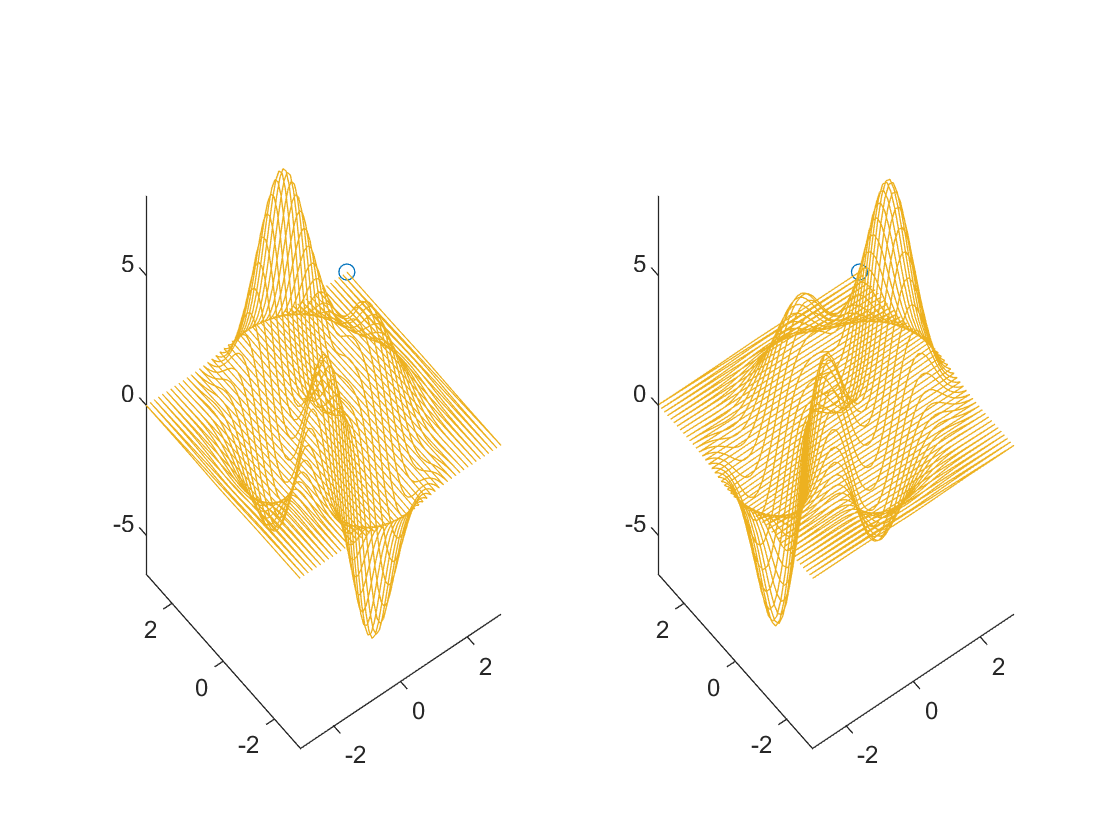

tiledlayout(1,2);
ax1 = nexttile;
ax2 = nexttile;
comet3(ax1,xvec,yvec,zvec)
comet3(ax2,yvec,xvec,zvec)

## Customizations

### Specify Animated Tail Length

Define the tail length as a percentage p of the length of each surface slice. The default is set to 10%. Plot the animation by passing $x$, $y$, $z$ and $p$ to `comet3`.

tailLength =0.65;
comet3(ax1,xvec,yvec,zvec, tailLength);

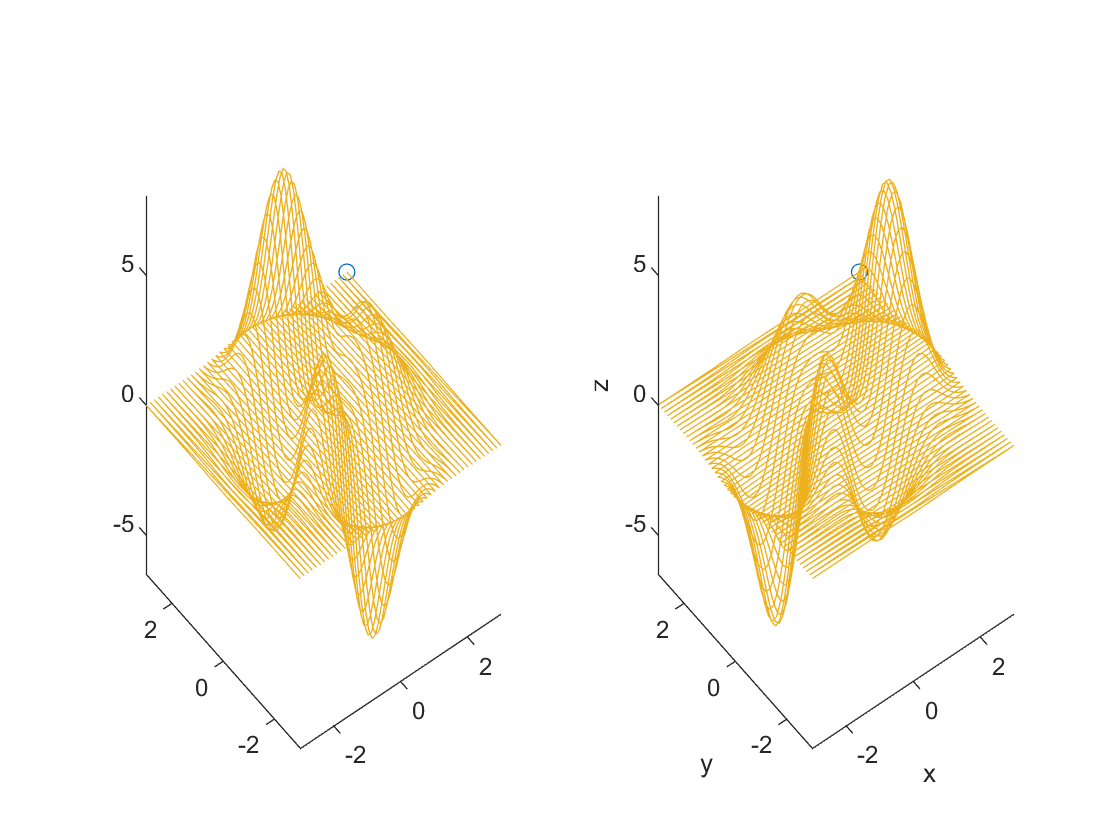

comet3(ax2,yvec,xvec,zvec, tailLength);

## Additional Information

### Documentation

Follow the link below to go to the documentation page to learn about the plot type in detail.

[comet3](https://www.mathworks.com/help/matlab/ref/comet3.html)